The function at the end of this file defines the PDE, by way of $\mathbf{f}(\mathbf{u})$ and its derivative. Note that the function will have access to all of the properties of a discretization, as if they were returned by `rectdisc`.

Now we solve and plot the result.

g = @(x,y) zeros(size(x));    % boundary condition
[U,X,Y] = newtonpde(@pde,g,100,[0 2.5],80,[0 1]);

Norm of residual = 15.0971
Norm of residual = 1.9805
Norm of residual = 0.075294
Norm of residual = 0.00013857
Norm of residual = 6.843e-09
Norm of residual = 1.9033e-11


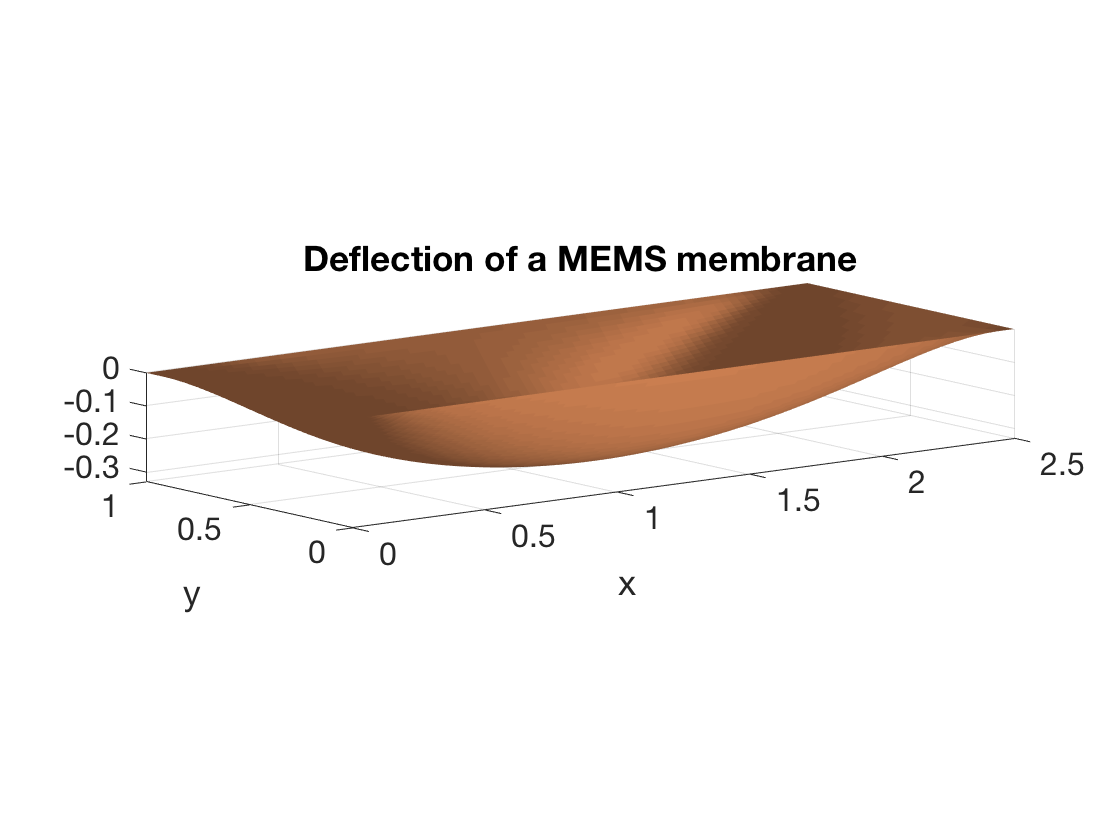

surfl(X,Y,U), colormap copper
view(-38,10)    % ignore this line
axis equal, shading flat    % ignore this line
xlabel x,  ylabel y    % ignore this line
title('Deflection of a MEMS membrane')    % ignore this line

function [F,J] = pde(U,X,Y,d)
    lambda = 1.5;
    LU = d.Dxx*U + U*d.Dyy';     % apply Laplacian
    F = LU - lambda./(U+1).^2;   % residual
        
    L = kron(d.Dyy,d.Ix) + kron(d.Iy,d.Dxx);  
    u = d.vec(U);
    J = L + sparse( diag(2*lambda./(u+1).^3) ); 
end